[cities, best_tour] = read_tsp();
D = pdist(cities);
Z = squareform(D);
best_length = tour_length(Z, best_tour);

%index = find((tour)'==1);
%tour([1, index]) = tour([index, 1]);

strategy = input("Please input the local search strategy (1 for inversion, " + ...
    "2 for insertion, 3 for displacement, 4 for swap:")

strategy =      3


switch strategy
    case 1
        f = @inversion_mutation;
    case 2
        f = @insertion_mutation;
    case 3
        f = @displacement_mutation;
    case 4
        f = @swap_mutation;
    otherwise
        disp("Invalid input, exit");
        exit;
end
    
tour = randperm(100)';   

iteration = 0;
%tours = zeros(100, 1001);
%while tour_length(Z, tour) >= 3*10^4
while iteration < 359
    for i = 1:1000
        new_tour = f(tour);
        difference = tour_length(Z, new_tour) - tour_length(Z, tour);
        if difference <= 0 
            tour = new_tour;  
        end
    end
    iteration = iteration + 1; 
end

fprintf("total iteration: %d\n", iteration);

total iteration: 359


tour_length(Z, tour)

ans =      2.415201948748877e+04


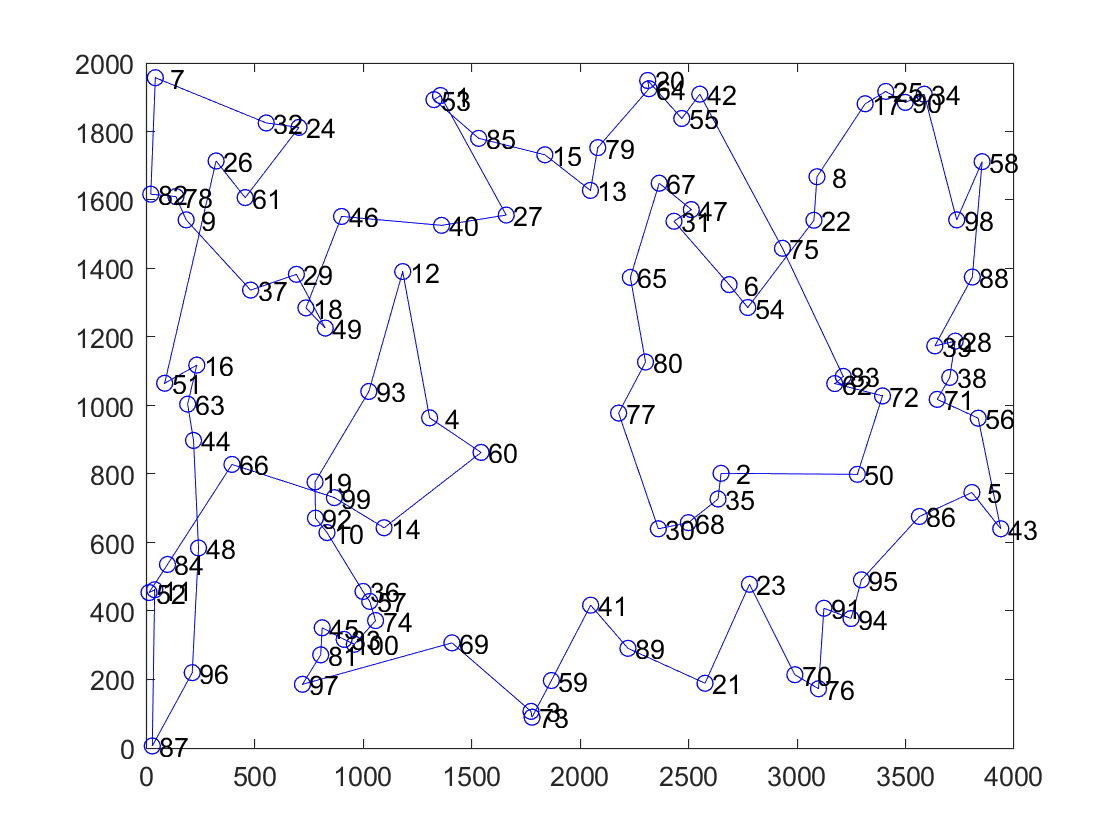

plot_tour(cities, tour)